## Task 4 Template matching

Load the images

%load the 
template = im2double(imread('template.png'));
% Downsample a bit since the template is way to large
template = imresize(template,.5);
original = im2double(imread('original_image.jpg'));

Since we have a green background and a bright white sky ( bright in all channels ) we want a dark sign, if we remove the red from the sign it'll be dark. so using the green or the blue channel is the best. To make the model les variant to lighting changes we increase the brightness by 4x to make the contrast between the darker and ligher areas greater.


% Remove the red channel making the sign black ( to not confuse it with the
% sky)
template = (template(:,:,2));


% Remove the red channel making the sign black
original_mod = original(:,:,2);
% Brighten the image, increasing the contrast between dark areas and bright
% one, this makes it easier to differentiate the black sign from the rest
% of the image
original_mod =  original_mod*4;

Here are the images after modification

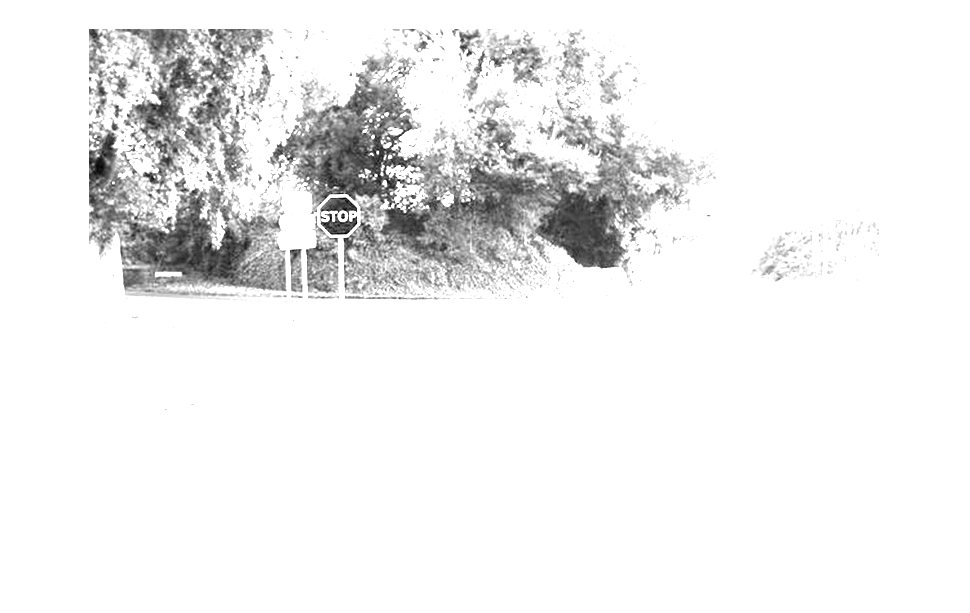

% Show the modified original image
imshow(original_mod);

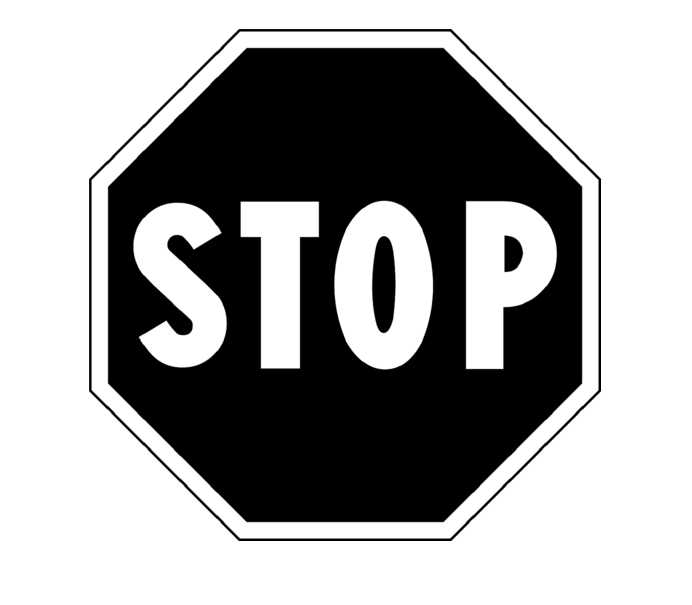

% Show the modified template image
imshow(template);

Performe template matching

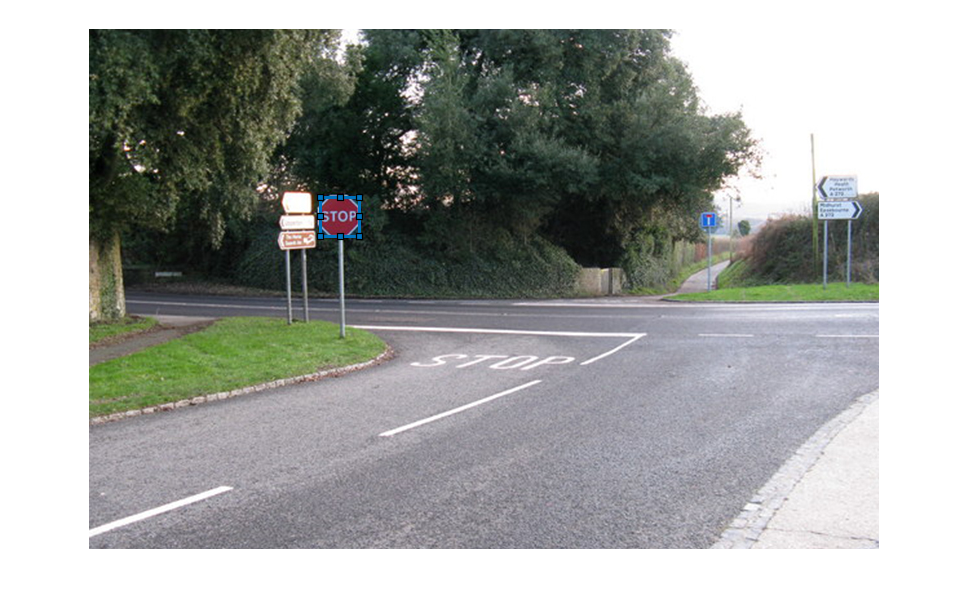

% This is expensive, but since we are not doing it in real time it is ok
% it downsamples to 75% of the size
ret = template_match(original_mod,template);
figure
hAx  = axes;
imshow(original,"Parent",hAx);
drawrectangle(hAx, 'Position', [ret(2)+1, ret(1)+1, ret(3), ret(4)]);

Create a function that template matches using a few different sizes of the template making the template matching algorithm scale invariant. 

function ret = template_match(img,template)
    ret = [0,0,0,0,0];
    % if template is too small, return
    if numel(template) < 20*20
        return 
    end
    % Use cross correlation to find where the images match the best
    corr = normxcorr2(template,img);
    conf = max(corr(:));
    ret(5) = conf;
    
    % get the size of the template
    ret(3) = size(template,1);
    ret(4) = size(template,2);
    
    % Get the location of the match
    [y,x] = find(corr==conf);
    % If for some reason the find tool fails, just return the zeros
    if numel(y) == numel(x) && numel(y) ==1
        ret(1) = y-size(template,1);
        ret(2) = x-size(template,2);
    end
    
    % Downsample and check if a smaller size gets a better match, if so 
    % we just return that match
    % This scaling factor could be changed, I just found 75% to be a good
    % Compromise between accuracy and time
    newtemplate = imresize(template,.75);
    newret = template_match(img,newtemplate);
    if newret(5) > conf
        
        ret = newret;
        return;
    end
end